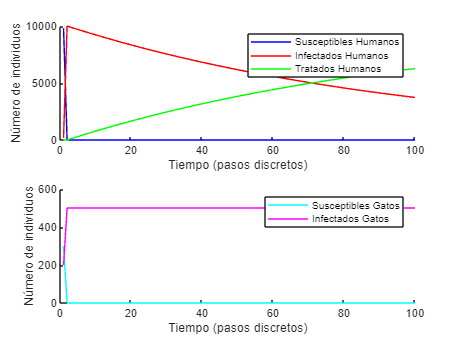

%%%Coded by Santiago Caballero Rosas,%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%       |\      _,,,---,,_                 %
% ZZZzz /,`.-'`'    -.  ;-;;,_             %
%      |,4-  ) )-,_. ,\ (  `'-'            %
%     '---''(_/--'  `-'\_)  Modelo SIR-CAT % 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Parámetros
beta_H = 0.02; % Tasa de infección en humanos
gamma_H = 0.01; % Tasa de recuperación en humanos
beta_G = 0.05; % Tasa de infección en gatos
gamma_G = 0.03; % Tasa de recuperación en gatos

% Poblaciones iniciales (números enteros)
S_H = 9800; % Humanos susceptibles
I_H = 200;  % Humanos infectados
T_H = 0;    % Humanos tratados (recuperados)
S_G = 300;  % Gatos susceptibles
I_G = 200;  % Gatos infectados

% Número total de humanos y gatos
Total_H = S_H + I_H + T_H;
Total_G = S_G + I_G;

% Número de pasos en la simulación
num_steps = 100;
dt = 1; % Incremento de tiempo (puede ajustarse según el nivel de detalle deseado)

% Almacenar los resultados
S_H_results = zeros(1, num_steps);
I_H_results = zeros(1, num_steps);
T_H_results = zeros(1, num_steps);
S_G_results = zeros(1, num_steps);
I_G_results = zeros(1, num_steps);
Total_H_results = zeros(1, num_steps);
Total_G_results = zeros(1, num_steps);

% Simulación
for t = 1:num_steps
    % Almacenar los resultados actuales
    S_H_results(t) = S_H;
    I_H_results(t) = I_H;
    T_H_results(t) = T_H;
    S_G_results(t) = S_G;
    I_G_results(t) = I_G;
    Total_H_results(t) = Total_H;
    Total_G_results(t) = Total_G;
    
    % Calcular las derivadas
    dS_H = round(-beta_H * I_G * S_H * dt);
    dI_H = round((beta_H * I_G * S_H - gamma_H * I_H) * dt);
    dT_H = round(gamma_H * I_H * dt);
    
    dS_G = round(-beta_G * S_G * I_G * dt);
    dI_G = round((beta_G * S_G * I_G - gamma_G * I_G) * dt);
    
    % Ajustar para mantener la población total constante
    % Humanos
    S_H = S_H + dS_H;
    I_H = I_H + dI_H;
    T_H = T_H + dT_H;
    
    % Verificar que las poblaciones no sean negativas
    if S_H < 0
        S_H = 0;
    end
    if I_H < 0
        I_H = 0;
    end
    if T_H < 0
        T_H = 0;
    end

    % Ajuste para mantener el total de humanos constante
    if S_H + I_H + T_H ~= Total_H
        diff = Total_H - (S_H + I_H + T_H);
        if I_H + diff >= 0
            I_H = I_H + diff;
        elseif S_H + diff >= 0
            S_H = S_H + diff;
        else
            T_H = T_H + diff;
        end
    end
    
    % Gatos
    S_G = S_G + dS_G;
    I_G = I_G + dI_G;
    
    % Verificar que las poblaciones no sean negativas
    if S_G < 0
        S_G = 0;
    end
    if I_G < 0
        I_G = 0;
    end

    % Ajuste para mantener el total de gatos constante
    if S_G + I_G ~= Total_G
        diff = Total_G - (S_G + I_G);
        if I_G + diff >= 0
            I_G = I_G + diff;
        else
            S_G = S_G + diff;
        end
    end
end

% Graficar los resultados
figure;
subplot(2,1,1);
hold on;
plot(1:num_steps, S_H_results, 'b', 'DisplayName', 'Susceptibles Humanos');
plot(1:num_steps, I_H_results, 'r', 'DisplayName', 'Infectados Humanos');
plot(1:num_steps, T_H_results, 'g', 'DisplayName', 'Tratados Humanos');
xlabel('Tiempo (pasos discretos)');
ylabel('Número de individuos');
legend;
hold off;

subplot(2,1,2);
hold on;
plot(1:num_steps, S_G_results, 'c', 'DisplayName', 'Susceptibles Gatos');
plot(1:num_steps, I_G_results, 'm', 'DisplayName', 'Infectados Gatos');
xlabel('Tiempo (pasos discretos)');
ylabel('Número de individuos');
legend;
hold off;


% Cálculo del Número de Reproducción Básico (R0)
R0_humans = beta_H / gamma_H;
fprintf('Número de Reproducción Básico en Humanos (R0): %.2f\n', R0_humans);

Número de Reproducción Básico en Humanos (R0): 2.00


disp('El número de reproducción básico (R0) indica el número promedio de casos secundarios generados por un caso primario en una población completamente susceptible. Si R0 > 1, la infección puede propagarse en la población; si R0 < 1, la infección decaerá.');

El número de reproducción básico (R0) indica el número promedio de casos secundarios generados por un caso primario en una población completamente susceptible. Si R0 > 1, la infección puede propagarse en la población; si R0 < 1, la infección decaerá.



R0_gatos = beta_G / gamma_G;
fprintf('Número de Reproducción Básico en Gatos (R0): %.2f\n', R0_gatos);

Número de Reproducción Básico en Gatos (R0): 1.67



% Cálculo de la proporción final de infectados
proportion_infected_humans = T_H / Total_H;
fprintf('Proporción final de humanos infectados y tratados: %.2f%%\n', proportion_infected_humans * 100);

Proporción final de humanos infectados y tratados: 63.03%


disp('La proporción final de infectados muestra el porcentaje de la población total que ha sido infectada y recuperada al final de la epidemia.');

La proporción final de infectados muestra el porcentaje de la población total que ha sido infectada y recuperada al final de la epidemia.



proportion_infected_gatos = I_G / Total_G;
fprintf('Proporción final de gatos infectados: %.2f%%\n', proportion_infected_gatos * 100);

Proporción final de gatos infectados: 100.00%



% Pico de la epidemia
[max_infected_humans, peak_time_humans] = max(I_H_results);
fprintf('Pico de la epidemia en humanos: %d infectados en el tiempo %d\n', max_infected_humans, peak_time_humans);

Pico de la epidemia en humanos: 9998 infectados en el tiempo 2


disp('El pico de la epidemia es el momento en el que el número de infectados alcanza su máximo. Este valor indica la carga máxima de la enfermedad en la población.');

El pico de la epidemia es el momento en el que el número de infectados alcanza su máximo. Este valor indica la carga máxima de la enfermedad en la población.



[max_infected_gatos, peak_time_gatos] = max(I_G_results);
fprintf('Pico de la epidemia en gatos: %d infectados en el tiempo %d\n', max_infected_gatos, peak_time_gatos);

Pico de la epidemia en gatos: 500 infectados en el tiempo 2



% Duración de la epidemia (cuando el cambio en infectados es cero o insignificante)
threshold = 0.01; % Umbral para el cambio insignificante
epidemic_duration_humans = num_steps; % Valor por defecto si no se encuentra un cambio insignificante
epidemic_duration_gatos = num_steps; % Valor por defecto si no se encuentra un cambio insignificante

for t = 2:num_steps
    if abs(I_H_results(t) - I_H_results(t-1)) < threshold
        epidemic_duration_humans = t;
        break;
    end
end

for t = 2:num_steps
    if abs(I_G_results(t) - I_G_results(t-1)) < threshold
        epidemic_duration_gatos = t;
        break;
    end
end

fprintf('Duración de la epidemia en humanos: %d pasos discretos\n', epidemic_duration_humans);

Duración de la epidemia en humanos: 100 pasos discretos


disp('La duración de la epidemia se define como el tiempo hasta que el cambio en la población de infectados se vuelve cero o insignificante, indicando que no hay nuevas infecciones ni recuperaciones.');

La duración de la epidemia se define como el tiempo hasta que el cambio en la población de infectados se vuelve cero o insignificante, indicando que no hay nuevas infecciones ni recuperaciones.



fprintf('Duración de la epidemia en gatos: %d pasos discretos\n', epidemic_duration_gatos);

Duración de la epidemia en gatos: 3 pasos discretos


disp('La duración de la epidemia se define como el tiempo hasta que el cambio en la población de infectados se vuelve cero o insignificante, indicando que no hay nuevas infecciones ni recuperaciones.');

La duración de la epidemia se define como el tiempo hasta que el cambio en la población de infectados se vuelve cero o insignificante, indicando que no hay nuevas infecciones ni recuperaciones.
